# **Wireless Communication**

## `Computer Assignment 1 `

### `Fatemeh Jalili - 810199398`

### **Problem #1 - Path loss & Shadowing**

clc, clear, close all;
rng(1)

Parameters:

numUser = 1e5;
d0 = 10;
D = 1000;
n = 4;
Pr_d0 = 10*log10(1e-6) + 30; %dBm
N0_dBm = -175;
N0 = 10 ^ (N0_dBm / 10) * 1e-3;  
BW = 1e6;

#### Part A

define distance of users array:

d = sort((D-d0) * sqrt(rand(numUser, 1)) + d0);

calculated recieved power based on given formula:

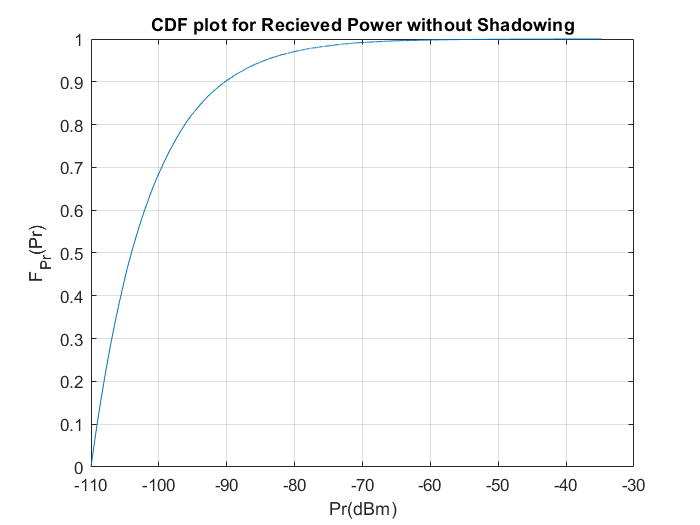

Pr_noShadow = Pr_d0 - 10 * n * log10(d ./ d0);
figure;
cdfplot(Pr_noShadow);
xlabel('Pr(dBm)');
ylabel('F_{Pr}(Pr)');
title("CDF plot for Recieved Power without Shadowing")

#### Part B

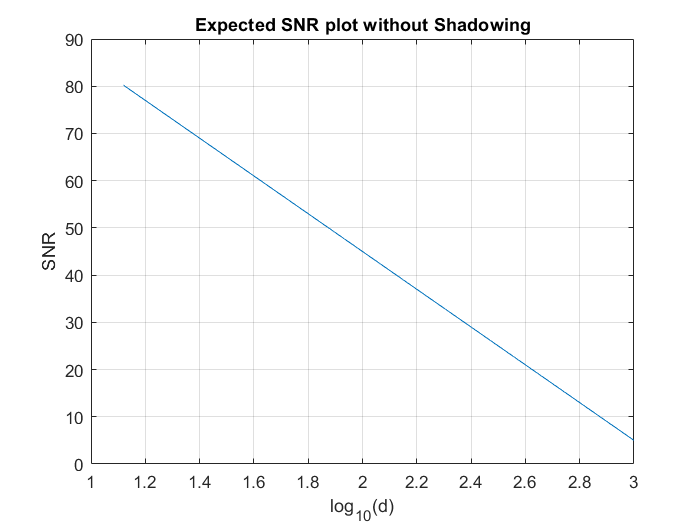

Pn = 10 * log10(N0 * BW * 1e3);
SNR = Pr_noShadow - Pn;
figure
plot(log10(d), SNR)
xlabel('log_{10}(d)');
ylabel('SNR');
title("Expected SNR plot without Shadowing")
grid on

#### Part C

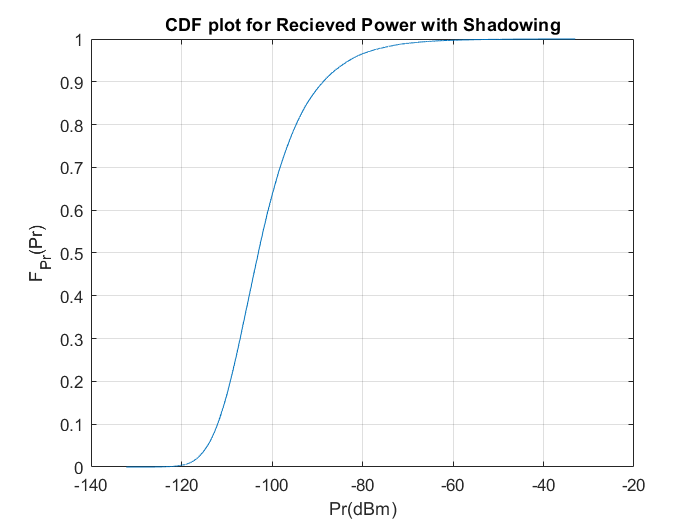

sigma = 5;
mu = 0;
X_dB = mu + sigma * randn(numUser, 1);
Pr_shadow = Pr_noShadow + X_dB;
figure;
cdfplot(Pr_shadow);
xlabel('Pr(dBm)');
ylabel('F_{Pr}(Pr)');
title("CDF plot for Recieved Power with Shadowing")

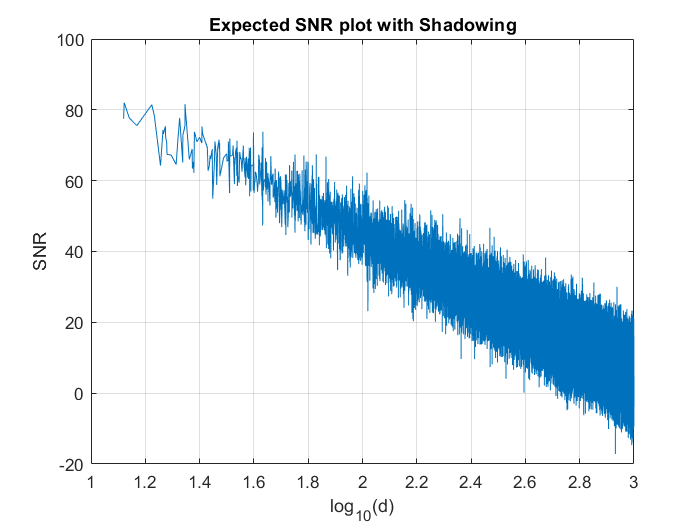

SNR_shadow = Pr_shadow - Pn;
figure
plot(log10(d), SNR_shadow)
xlabel('log_{10}(d)');
ylabel('SNR');
title("Expected SNR plot with Shadowing")
grid on

#### Part D

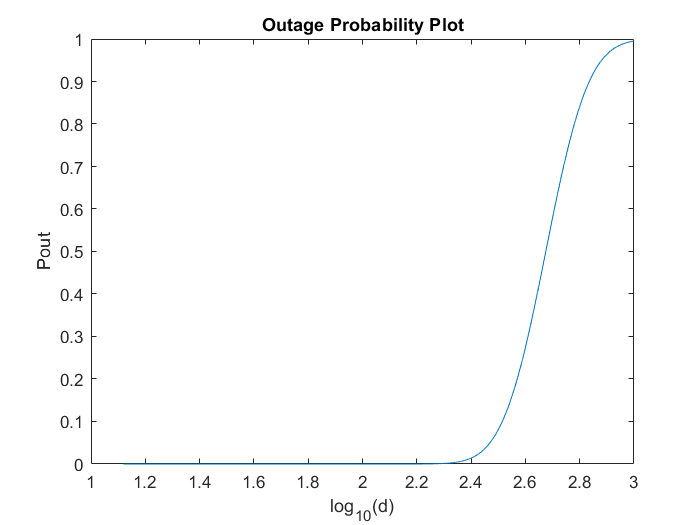

SNR_min = 18; %dB
Pout = 1 - qfunc((SNR_min - SNR) / sigma);
plot(log10(d), Pout)
xlabel('log_{10}(d)');
ylabel('Pout');
title("Outage Probability Plot")

#### Part E

% method 1
% idx = find(SNR <= SNR_min);
% d1 = d(idx(1));
% s_coverage_sim1 = pi*(d1^2 - d0^2);
% C1 = s_coverage_sim1 / (pi * D ^ 2);
% fprintf('method1 : Based on Simulation Results, Coverage area of BS is %f where C = %f', s_coverage_sim1, C1)
%method 2
Ncoverange = sum(SNR_shadow > SNR_min);
C3 = Ncoverange / numUser;
s_coverage_sim2 = pi * C3 * D ^ 2;
fprintf('Based on Simulation Results, Coverage area of BS is %f where C = %f', s_coverage_sim2, C3)

Based on Simulation Results, Coverage area of BS is 823097.275241 where C = 0.262000


Pr_min = SNR_min + (N0_dBm + 10 * log10(BW));
Pr_D = Pr_d0 - 10 * n * log10(D / d0);
a = (Pr_min - Pr_D) / sigma;
b = 10 * n * log10(exp(1)) / sigma;
C2 = qfunc(a) + exp((2 - 2 * a * b) / b^2) * qfunc((2 - a * b) / b);
s_coverage_theor = pi * C2 * D ^ 2;
fprintf('Based on Theoritical Results, Coverage area of BS is %f where C = %f', s_coverage_theor, C2)

Based on Theoritical Results, Coverage area of BS is 826877.590298 where C = 0.263203

**Problem #2 - Fading Channels**

clc, clear, close all;
rng(6)

Parameters:

N = 15; 
fc = 3e9;
c = 3e8;
lambda = c / fc;
v = 30;
simulationTimes = 1e5;

#### Part A

power = zeros(1, simulationTimes);
for iter = 1 : simulationTimes
    theta = 0.5 * pi * rand(N, 1);
    tau = 9 * rand(N, 1) + 1;
    sigma = sqrt(1e-3 * tau .^ (-4) / 2);
    ri = sigma .* randn(N, 1);
    rq = sigma .* randn(N, 1);
    alpha = abs(ri + 1i * rq);
    fD = v * cos(theta) / lambda;
    phi = 2 * pi * (fc - fD) .* tau * 1e-6;
    h = alpha .* exp(-1i * phi);
    power(iter) = sum(abs(h) .^ 2);
end
Eh2 = mean(power);
fprintf('E{|h|^2} = %f', Eh2)

E{|h|^2} = 0.000552

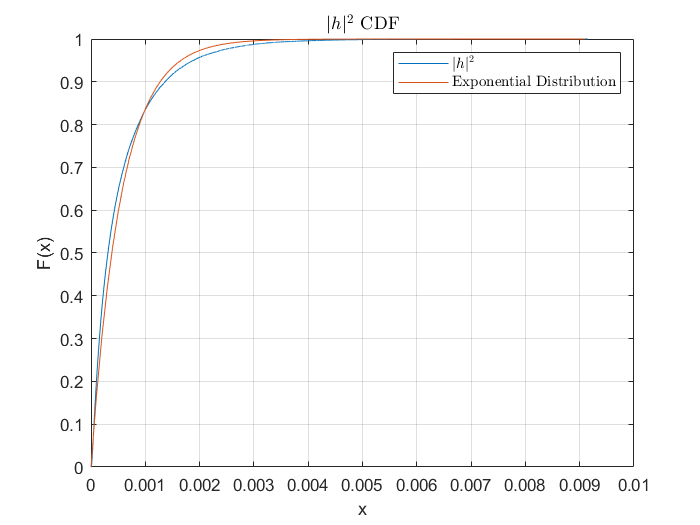

figure
cdfplot(power)
hold on
compare = fitdist(power','Exponential');
x = 0 : 0.0001 : max(power);
plt = cdf(compare,x);
plot(x, plt)
grid on;
title('$|h|^2$ CDF','Interpreter','latex')
legend('$|h|^2$', 'Exponential Distribution','Interpreter','latex');

#### Part B

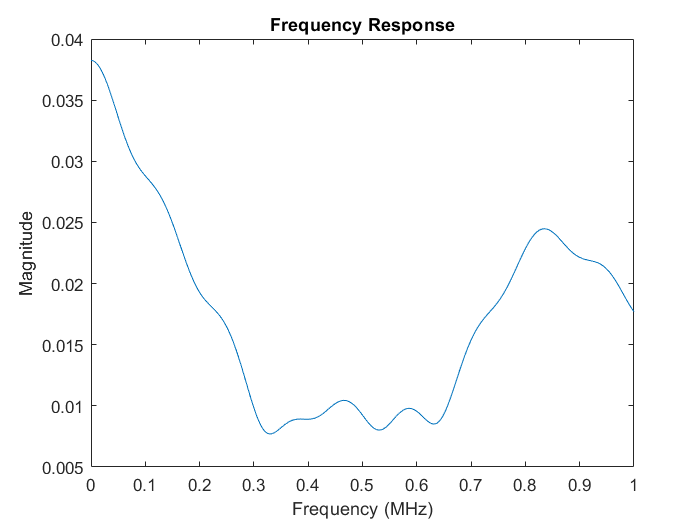

theta = 0.5 * pi * rand(N, 1);
tau = 9 * rand(N, 1) + 1;
sigma = sqrt(1e-3 * tau .^ (-4) / 2);
ri = sigma .* randn(N, 1);
rq = sigma .* randn(N, 1);
alpha = abs(ri + 1i * rq);
fD = v * cos(theta) / lambda;
freq = (0 : 1e6-1).';
H = zeros(length(freq), 1);
for i = 1 : N
    phi = 2 * pi * (freq - fD(i)) .* tau(i) * 1e-6;
    H = H + alpha(i) * exp(-1i * phi);
end
figure;
plot(freq / 1e6, abs(H));
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('Frequency Response');

**Problem #3 - Power Delay Profile (PDP)**

clc, clear, close all;
rng(1)

syms tau;
syms delta_t;

PDP = double(sinc(0 * delta_t));
mu_m = double(int(tau * PDP, tau, 0, 10) / int(PDP, tau, 0, 10));
sigma_m = double(sqrt(int((tau - mu_m) ^ 2 * PDP, tau, 0, 10) / int(PDP, tau, 0, 10)));

fprintf('Averange Power Delay Spread = %f\nRMS Power Delay Spread = %f', mu_m, sigma_m)

Averange Power Delay Spread = 5.000000
RMS Power Delay Spread = 2.886751

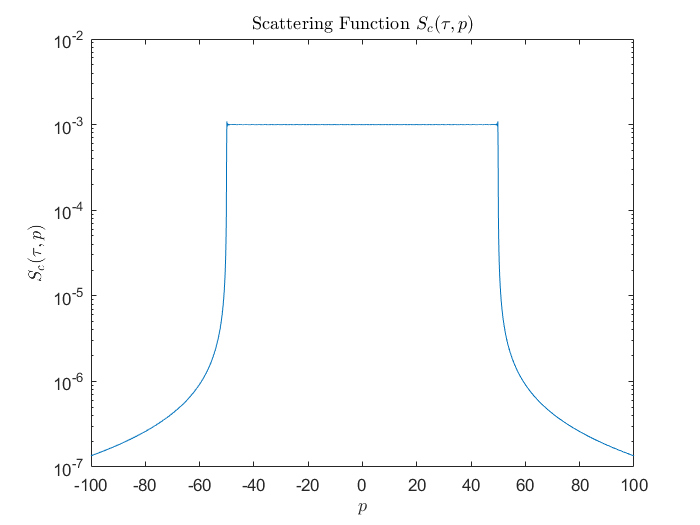


fs = 1e6;
delta_t = -5: 1 / fs : 5;
freq = (-length(delta_t)/2 : length(delta_t)/2 - 1) * fs / length(delta_t);
Rc = sinc(100 * delta_t);
Sc = abs(fftshift(fft(Rc) / length(delta_t)));
semilogy(freq, Sc);
xlim([-100, 100])
title('Scattering Function $S_c(\tau, p)$', 'Interpreter', 'latex');
xlabel('$p$', 'Interpreter', 'latex');
ylabel('$S_c(\tau, p)$', 'Interpreter', 'latex');

max_Sc = max(Sc);
threshold = max_Sc / 10;
indices = find(Sc >= threshold);
tendB_BW_freqs = freq(indices);
tendB_BW = max(tendB_BW_freqs) - min(tendB_BW_freqs);



**Problem #4 - Power Allocation**

clc, clear, close all;
rng(1)

G_cell = cell(1, 5);   
N0_cell = cell(1, 5);   
Pmax_cell = cell(1, 5); 

fR_cell = cell(1, 5); 
Popt_cell = cell(1, 5); 
Pmax_Popt_cell = cell(1, 5); 

for i = 1:5
    filename = ['a' num2str(i) '.mat']; 
    data = load(filename); 
    G_cell{i} = data.G;
    N0_cell{i} = data.N0;
    Pmax_cell{i} = data.P_max;
end

fR_max = zeros(1, 5);
Pt_max = zeros(1, 5);
Pt_opt = zeros(1, 5);

for datasetNum = 1 : numel(G_cell)
    G = G_cell{datasetNum};
    N0 = N0_cell{datasetNum};
    Pmax = Pmax_cell{datasetNum};
    
    alpha = 1e-1;
    thre = 1e-4;
    P = ones(1, length(Pmax)) .* Pmax / 2;
    SINR = ones(1, length(Pmax));
    SINR_max = ones(1, length(Pmax));
    R = ones(1, length(Pmax));
    R_max = ones(1, length(Pmax));
    fR = [];
    whileRep = 0;
    dist = ones(1, length(Pmax));
    
    for i = 1 : length(Pmax) 
            Pj = P;
            Pj(i) = [];
            Gij = G(i, :);
            Gij(i) = [];
            SINR_max(i) = P(i) * G(i, i) / (N0(i) + Pj * Gij.');
            R_max(i) = log2(1 + SINR_max(i));
    end
    fR_max(datasetNum) = sum(log2(R_max));
    Pt_max(datasetNum) = sum(Pmax);
    
    while norm(dist ./ P) > thre
        for i = 1 : length(Pmax) 
            Pj = P;
            Pj(i) = [];
            Gij = G(i, :);
            Gij(i) = [];
            SINR(i) = P(i) * G(i, i) / (N0(i) + Pj * Gij.');
            R(i) = log2(1 + SINR(i));
            stepi = SINR(i) / (R(i) * P(i) * (SINR(i) + 1));
            stepj = 0;
            for j = 1 : length(Pmax)
                if j ~= i
                    stepj = stepj + ...
                        SINR(j) ^ 2 * G(j, i) / (G(j, j) * R(j) * P(j) * (SINR(j) + 1));
                end
            end
            Pi_next = P(i) + alpha * (stepi - stepj);
            if Pi_next > Pmax(i)
                Pi_next = Pmax(i);
            end
            dist(i) = P(i) - Pi_next;
            P(i) = Pi_next;
        end
        whileRep = whileRep+1;
        fR = cat(2, fR, sum(log2(R)));
    end
    Pt_opt(datasetNum) = sum(P);
    
    fR_cell{datasetNum} = fR;
    Popt_cell{datasetNum} = P;
    Pmax_Popt_cell{datasetNum} = Pmax - P; 
end

results:

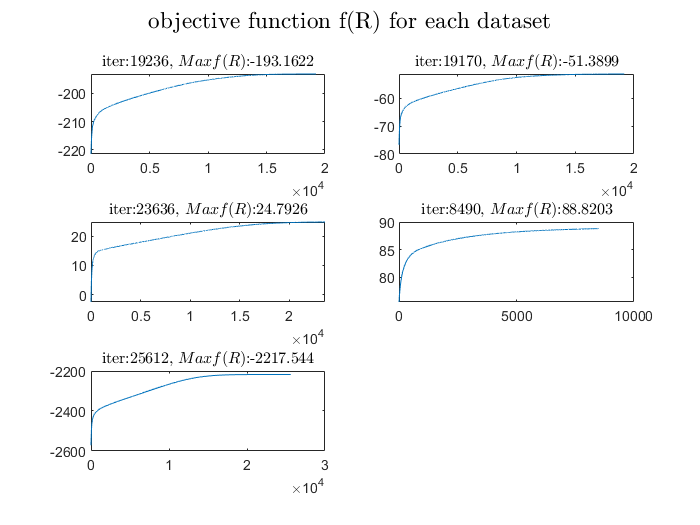

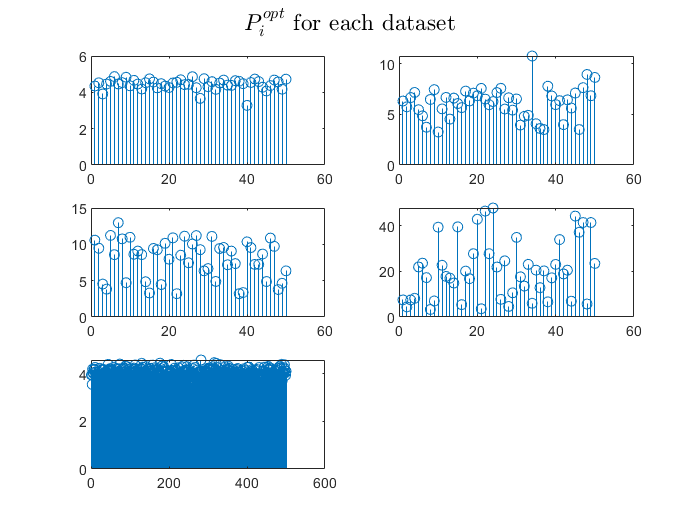

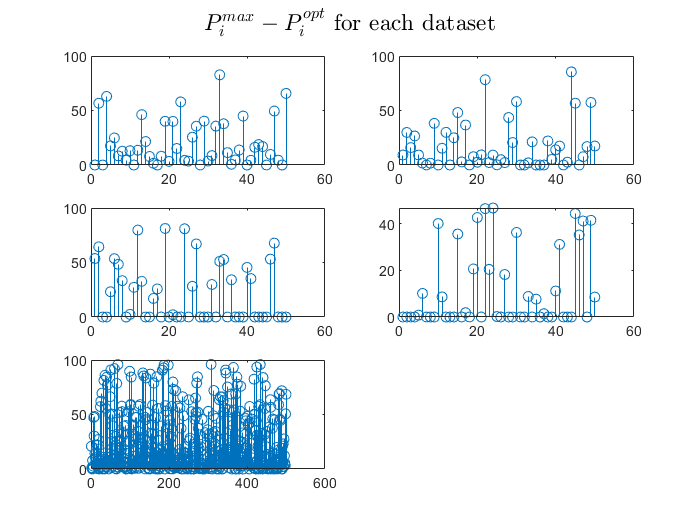

for datasetNum = 1 : 5
    figure(1)
    subplot(3, 2, datasetNum)
    plot(fR_cell{datasetNum})
    title(['iter:', num2str(size(fR_cell{datasetNum}, 2)),...
        ', $Max{f(R)}$:', num2str(fR_cell{datasetNum}(end))], 'Interpreter','latex')
    sgtitle('objective function f(R) for each dataset', 'Interpreter','latex');
    
    figure(2)
    subplot(3, 2, datasetNum)
    stem(Popt_cell{datasetNum})
    sgtitle('$P_i^{opt}$ for each dataset', 'Interpreter','latex');
    
    figure(3)
    subplot(3, 2, datasetNum)
    stem(Pmax_Popt_cell{datasetNum})
    sgtitle('$P_i^{max}-P_i^{opt}$ for each dataset','Interpreter','latex');
    
end

for datasetNum = 1 : 5
    fprintf('objective function improvement for dataset %d is %f\n',datasetNum, fR_cell{datasetNum}(end) - fR_max(datasetNum))
    fprintf('Savings in transmission power for dataset %d is %f\n',datasetNum, Pt_max(datasetNum) - Pt_opt(datasetNum))
    fprintf('------------------------------------')
end

objective function improvement for dataset 1 is 27.783139


Savings in transmission power for dataset 1 is 994.511817


------------------------------------

objective function improvement for dataset 2 is 25.362350


Savings in transmission power for dataset 2 is 855.218639


------------------------------------

objective function improvement for dataset 3 is 27.327010


Savings in transmission power for dataset 3 is 1090.606966


------------------------------------

objective function improvement for dataset 4 is 13.235351


Savings in transmission power for dataset 4 is 559.655023


------------------------------------

objective function improvement for dataset 5 is 343.132141


Savings in transmission power for dataset 5 is 11832.288067


------------------------------------